So here's a tutorial on the basics of using my MATLAB tools. All paths are relative to the folder `.\GUIDesign\`

First, you're going to need to use `PhageGUIcrop_V2` to crop your files. Here's an image detailing its function:

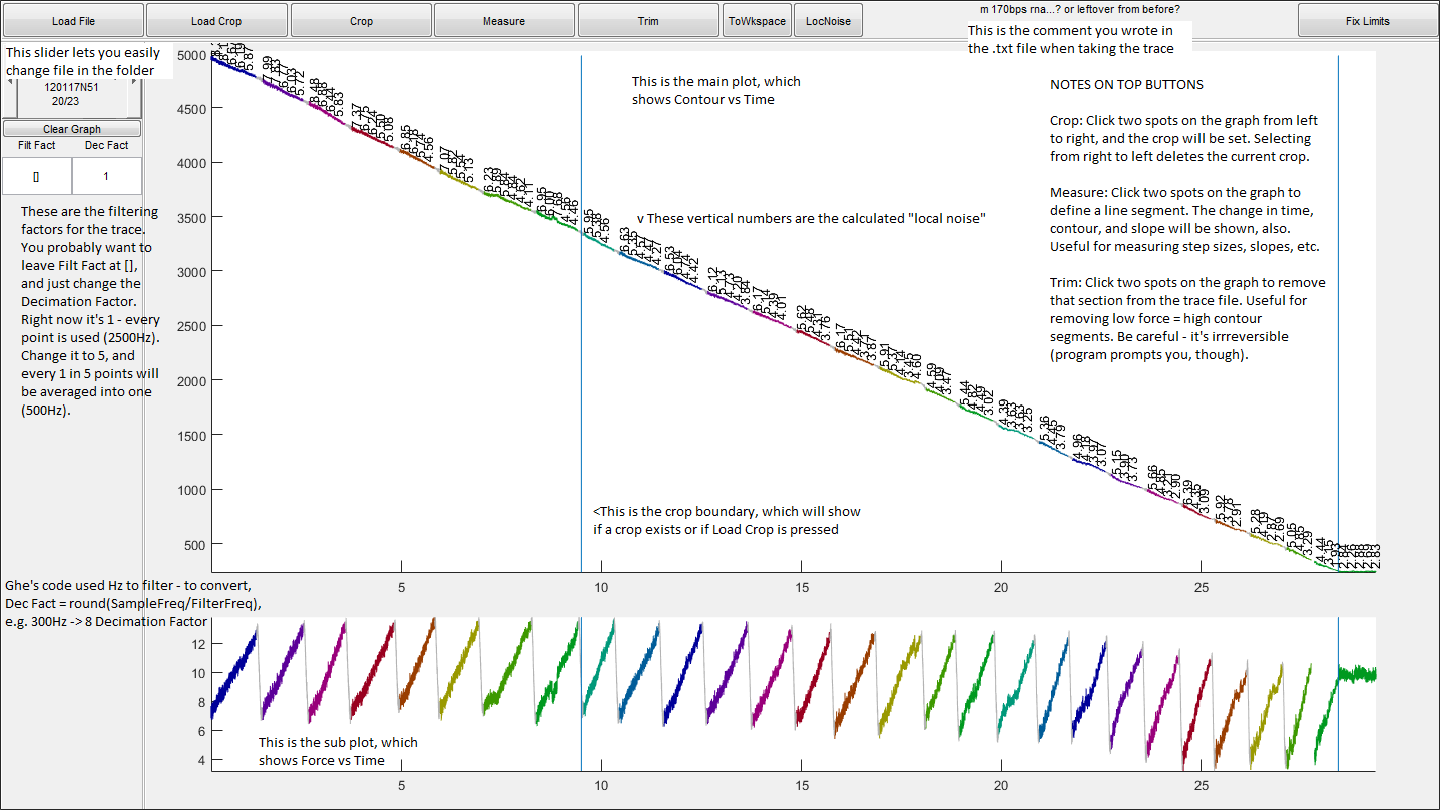

%Add requried paths
thispath = fileparts(which('Stepfind_Tutorial.mlx'));
addpath (thispath)
addpath ([thispath '\..\StepFind_KV\'])
im = imread('img_phageguicrop.PNG');
scrsz = [1 1 1920 1080];
fglm = [scrsz(3:4)/8, .75* scrsz(3:4)];
fg = figure('Name', 'PhageGUIcrop_V2 Example', 'Position', fglm);
ax = axes('Units', 'Normalized', 'Position', [0 0 1 1]);
image(ax, im);
ax.XTick = [];
ax.YTick = [];

It uses the same crops defined by Ghe, so it's backwards-compatible.

After you've cropped all your files, you need to gather the feedback cycles. Run `.\StepFind_Hist\Iterate_GatherFCs` and select your phage*.mat files. Oh, for folders to include on MATLAB's path, running `PhageGUIcrop_V2` should add everything you need - if you get a file not found error, try running `PhageGUIcrop_V2` once first, or adding `.\StepFind_KV\`

Iterate_GatherFCs will output a cell of the feedback cycles within the crop boundaries. As an example, I've done this with the 7-12pN DNA data from Dec 2016, saved as variable `d` in `dec12raw.mat`

load dec12raw.mat

Now, some feedback cycles might not be well-behaved if they're small - this is especially the case with Ghe-processed files. We can see the length of each trace using `cellfun`:

dlen = cellfun(@length, d)

dlen =         3741        3849        4273        3602        3928        4416        4049        3532        3165        3740        3608           1        3938        2983        3280        3636        3282        3616        3050        3484        3347        2837        2505        3128        3534        3323        3049        2880        1243        2957        2772        1997        2777        2737        2609        3432        3967        3890        3934        3553        3652        2607        4409           1        4349        4499        4870        3552        2143        4941

Notice how some lengths are only a few points - these are artifacts from the trace segmenting algorithm. Let's remove them:

d2 = d(dlen>100); %Removes all feedback cycles fewer than 100 points
d2len = cellfun(@length, d2)

d2len =         3741        3849        4273        3602        3928        4416        4049        3532        3165        3740        3608        3938        2983        3280        3636        3282        3616        3050        3484        3347        2837        2505        3128        3534        3323        3049        2880        1243        2957        2772        1997        2777        2737        2609        3432        3967        3890        3934        3553        3652        2607        4409        4349        4499        4870        3552        2143        4941        4565        3772

The lengths look better now. You might want to filter them, too:

d2F5 = cellfun(@(x)windowFilter(@mean, x, [], 5), d2, 'Uni', 0);

That filters all the traces with a decimation window of 5 - i.e. from 2500Hz to 500Hz.

If you want an easier way to filter, create this anonymous function (this will end up in your workspace when you run this code line):

filterFCs = @(fc, dec) cellfun(@(x)windowFilter(@mean, x, [], dec), fc, 'Uni', 0);

And call it like this:

d2F5v2 = filterFCs(d2, 5);
eq = isequal(d2F5, d2F5v2);
fprintf('The two cells, d2F5 and d2F5v2, are%s equal\n', 'n''t'*~eq)

The two cells, d2F5 and d2F5v2, are    equal


Remember that Gheorge's Filter Frequency converts to my Decimation Factor by:

%DecFact=round(SampFreq/FilFreq)
DecFact = round(2500/300); 
fprintf('For 300Hz filter frequency, decimation factor = %d\n', DecFact)

For 300Hz filter frequency, decimation factor = 8


You probably want to `save` these numbers to easily access them later.

%save('myWorkspace') %This saves all of your workspace variables to .\myWorkspace.mat. You could also do save('myWorkspace', 'd*), which saves all of your workspace variables that start with d (d, d2d dlen, d2len, d2F5, d2F5v2)

Now, we need to apply the Kalafut-Visscher stepfinding algorithm, using the function `.\StepFind_KV\BatchKV`

[----------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------]
[
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�|
�]
BatchKV took 6.85s


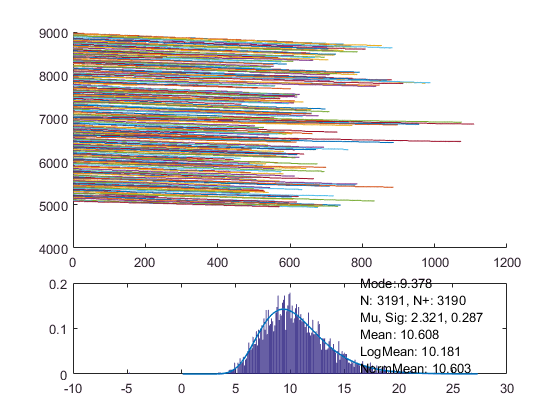

%BatchKV( FeedbackCycles , single( PenaltyFactor ))
BatchKV(d2F5, single(5)); %Applies K-V to all the feedback cycles in d2F5 with a penalty factor of 5.

Not bad - a few seconds to process every trace. For unfiltered traces, it'll take longer: speed is nlog(n), where n is the number of points.

In the figure, the top graph shows every feedback cycle with its staircase. The bottom histogram shows the data binned with a lognormal fit, with values in text. 

`BatchKV` can be sped up with parallel processing (doesn't work in this tutorial script). Start a parallel pool with `gcp`

gcp; %Creates parallel pool

Starting parallel pool (parpool) using the 'local' profile ... connected to 2 workers.


% BatchKV(d2F5, single(5));

Have fun playing with numbers!